clc;
clear;

%read table
filename='laughter-corpus.csv';
data=readtable(filename);
gender=data.Gender;
role=data.Role;
duration=data.Duration;

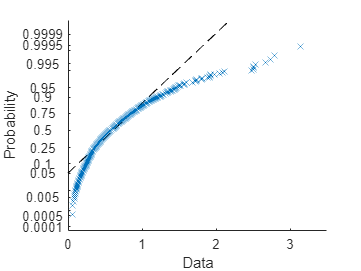

%to ensure the type of the distribution of duration
plot(fitdist(duration,"Normal"),'PlotType',"probability")

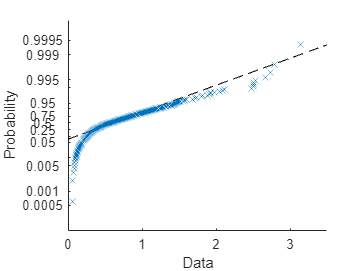

plot(fitdist(duration,"tLocationScale"),'PlotType',"probability")

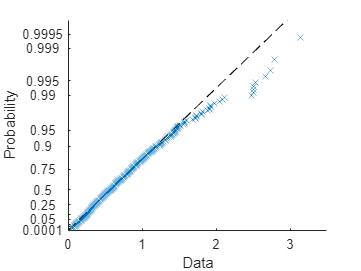

plot(fitdist(duration,"Gamma"),'PlotType',"probability")

F=63;%female number
M=57;%male number
C=60;%caller number
R=60;%receiver number

N=size(gender);
N=N(1);%total laughter event number
D=sum(duration);
muD=D/N;%mean of laughter duration in every event
muN=N/(F+M);%mean of laughter event number of one person

FN=0;%female laughter event numbers
MN=0;%male laughter event numbers
CN=0;%caller laughter event numbers
RN=0;%receiver laughter event numbers

FD=0;%female laughter duration
MD=0;%male laughter duration
CD=0;%caller laughter duration
RD=0;%receiver laughter duration

Dss=0;%duration variance
FDss=0;%female duration variance
MDss=0;%male duration variance
CDss=0;%caller duration variance
RDss=0;%receiver duration variance

%store duration data seperately
durationF=[];
durationM=[];
durationC=[];
durationR=[];

for i=1:N
    if strcmp(gender(i),'Female')==1
        FD=FD+duration(i);
        FN=FN+1;
        durationF=[durationF duration(i)];
    elseif strcmp(gender(i),'Male')==1
        MD=MD+duration(i);
        MN=MN+1;
        durationM=[durationM duration(i)];
    end
    Dss=Dss+(duration(i)-muD)^2/N;
    i=i+1;
end

for j=1:N
    if strcmp(role(j),'Caller')==1
        CD=CD+duration(j);
        CN=CN+1;
        durationC=[durationC duration(j)];
    elseif strcmp(role(j),'Receiver')==1
        RD=RD+duration(j);
        RN=RN+1;
        durationR=[durationR duration(j)];
    end
    j=j+1;   
end

hFN=FN/F;%mean of laughter number of female
hMN=MN/M;%mean of laughter number of male
hCN=CN/C;%mean of laughter number of caller
hRN=RN/R;%mean of laughter number of receiver
hFD=FD/FN;%mean of laughter duration of female laughter events
hMD=MD/MN;%mean of laughter duration of male laughter events
hCD=CD/CN;%mean of laughter duration of caller laughter events
hRD=RD/RN;%mean of laughter duration of receiver laughter events

i=0;
j=0;

for i=1:N
    if strcmp(gender(i),'Female')==1
        FDss=FDss+(duration(i)-hFD)^2/FN;
    elseif strcmp(gender(i),'Male')==1
        MDss=MDss+(duration(i)-hMD)^2/MN;
    end
    i=i+1;
end

for j=1:N
    if strcmp(role(j),'Caller')==1
        CDss=CDss+(duration(j)-hCD)^2/CN;
    elseif strcmp(role(j),'Receiver')==1
        RDss=RDss+(duration(j)-hRD)^2/RN;
    end
    j=j+1;   
end

Ds=sqrt(Dss);%duration standard deviation
FDs=sqrt(FDss);%female duration standard deviation
MDs=sqrt(MDss);%male duration standard deviation
CDs=sqrt(CDss);%caller duration standard deviation
RDs=sqrt(RDss);%receiver duration standard deviation

OFN=FN

OFN = 496

OMN=MN

OMN = 346

OCN=CN

OCN = 505

ORN=RN

ORN = 337


OFD=FD

OFD = 352.0040

OMD=MD

OMD = 209.7560

OCD=CD

OCD = 376.6120

ORD=RD

ORD = 185.1480


EFN=muN*F

EFN = 442.0500

EMN=muN*M

EMN = 399.9500

ECN=muN*C

ECN = 421

ERN=muN*R

ERN = 421


EFD=muD*FN

EFD = 330.9180

EMD=muD*MN

EMD = 230.8420

ECD=muD*CN

ECD = 336.9226

ERD=muD*RN

ERD = 224.8374

%Chi square
CD1=(OFN-EFN)^2/EFN+(OMN-EMN)^2/EMN%chi square of male and female laughter number

CD1 = 13.8617

CD2=(OCN-ECN)^2/ECN+(ORN-ERN)^2/ERN%chi square of caller and receiver laughter number

CD2 = 33.5202

pCD1=(CD1^(-0.5)*exp(-0.5*CD1))/(2^0.5*gamma(0.5))%The probability density function of CD1

pCD1 = 1.0470e-04

pCD2=(CD2^(-0.5)*exp(-0.5*CD2))/(2^0.5*gamma(0.5))%The probability density function of CD2

pCD2 = 3.6261e-09


%Chi square
CD3=(OFD-EFD)^2/EFD+(OMD-EMD)^2/EMD%chi square of male and female duration

CD3 = 3.2697

CD4=(OCD-ECD)^2/ECD+(ORD-ERD)^2/ERD%chi square of caller and receiver duration

CD4 = 11.6816

pCD3=(CD3^(-0.5)*exp(-0.5*CD3))/(2^0.5*gamma(0.5))%The probability density function of CD3

pCD3 = 0.0430

pCD4=(CD4^(-0.5)*exp(-0.5*CD4))/(2^0.5*gamma(0.5))%The probability density function of CD4

pCD4 = 3.3926e-04

pd = fitdist(duration,'tLocationScale');
a = fitdist(duration,'tLocationScale')

a =   tLocationScaleDistribution

  t Location-Scale distribution
       mu = 0.590379   [0.563844, 0.616913]
    sigma = 0.300489   [0.276697, 0.326326]
       nu =  3.81557   [2.94095, 4.95029]


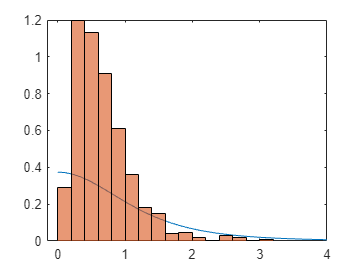

x=[0:0.1:4];
y=tpdf(x,a.nu);

figure
plot(x,y)
hold on
histogram(duration,'Normalization','pdf')
hold off

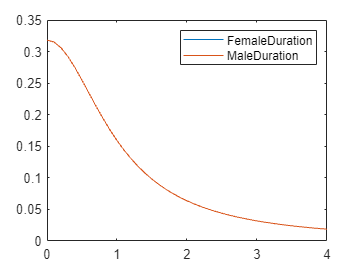

x = [0:0.1:4];
pdF=fitdist(durationF.','tLocationScale');
y1 = tpdf(x,1); 
pdM=fitdist(durationM.','tLocationScale');
y2 = tpdf(x,1); 
plot(x,y1); 
hold on
plot(x,y2); 
legend FemaleDuration MaleDuration
hold off

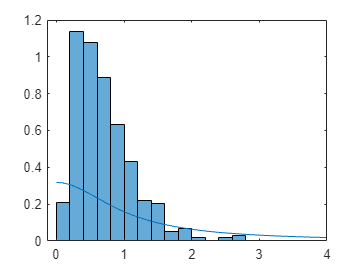

figure
histogram(durationF,'Normalization','pdf')
line(x,y1)

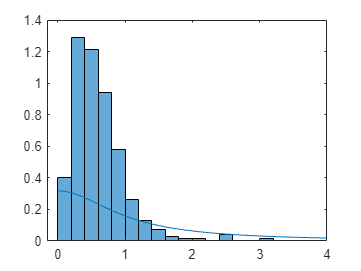

figure
histogram(durationM,'Normalization','pdf')
line(x,y2)

pdC=fitdist(durationC.','tLocationScale');
y3 = tpdf(x,k34); 

Unrecognized function or variable 'k34'.

pdR=fitdist(durationR.','tLocationScale');
y4 = tpdf(x,k34); 
plot(x,y3); 
hold on
plot(x,y4); 
legend CallerDuration ReceiverDuration
hold off

figure
histogram(durationC,'Normalization','pdf')
line(x,y3)

figure
histogram(durationR,'Normalization','pdf')
line(x,y4)
%to ensure the type of the distribution of duration

plot(fitdist(duration,"Normal"),'PlotType',"probability")

plot(fitdist(duration,"logistic"),'PlotType',"probability")

plot(fitdist(duration,"Gamma"),'PlotType',"probability")